## 拟合算法

1.拟合的结果是得到一个确定的曲线

2.残差平方和：L = $\sum_{i=1}^n \left(y_i -{\textrm{kx}}_i -b\right)^2$ --要尽量的小

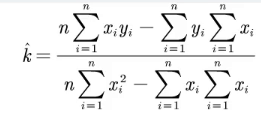       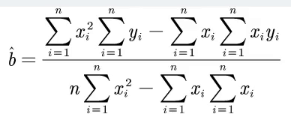

3.拟合优度（可决系数）$R^2$

        A.越接近 1，说明误差平方和越接近 0， 拟合效果越好 

        B.拟合函数必须是线性函数（其他函数直接看 SSE 即可）

        C.总体平方和（SST）、误差平方和（SSE）、回归平方和（SSR）

           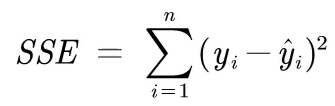   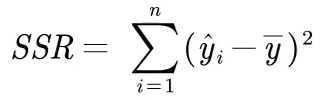

4.线性函数

        A.对变量为线性

        B.对参数为线性

        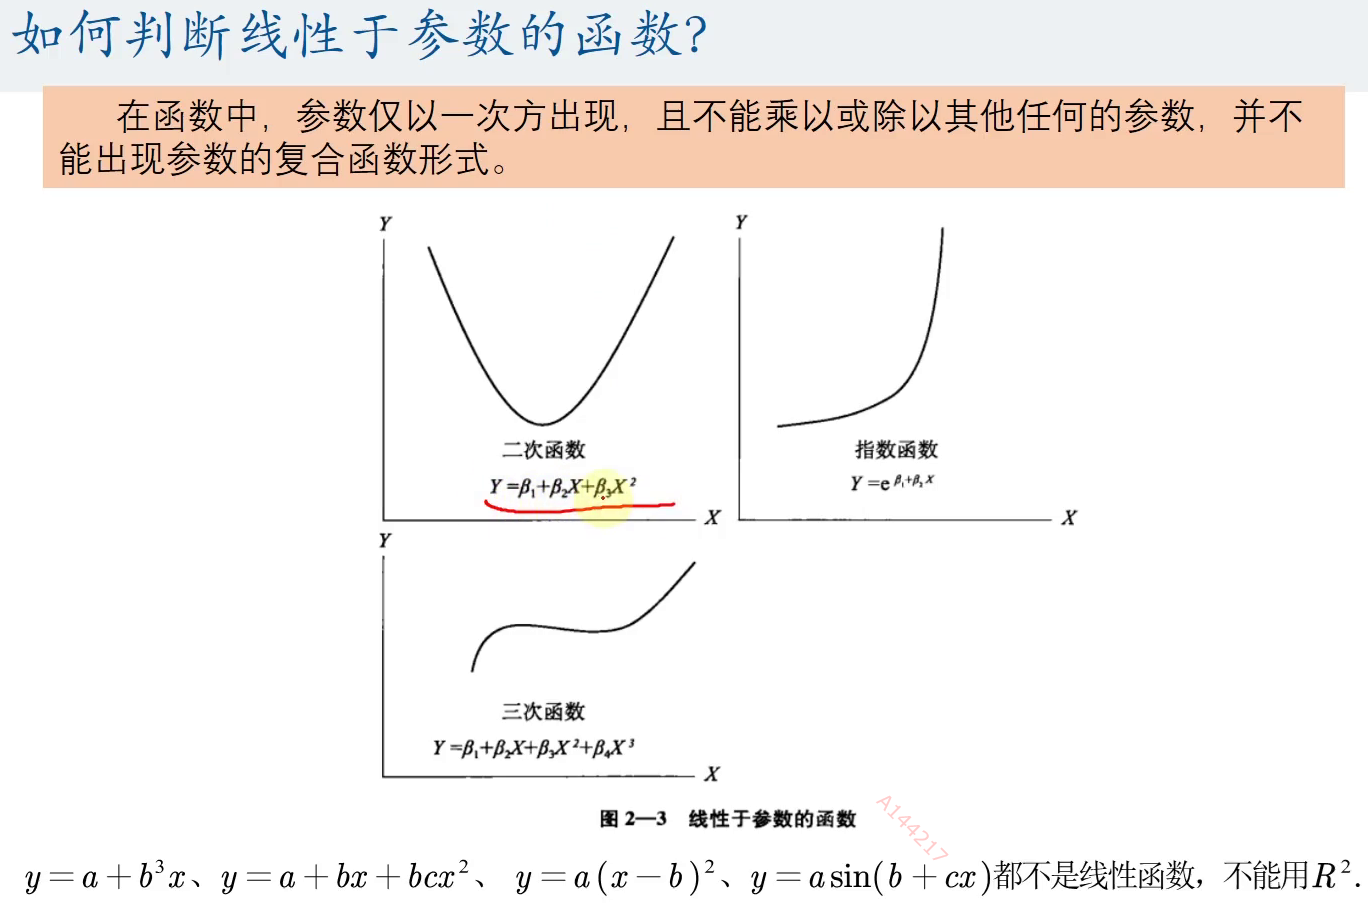

5. Curve Fitting 工具：

        A自定义公式

        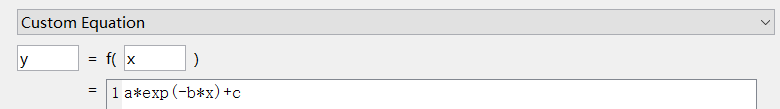

clc
clear

x = [4.2 5.9 2.7 3.8 3.8 5.6 6.9 3.5 3.6 2.9 4.2 6.1 5.5 6.6 2.9 3.3 5.9 6 5.6];
y = [8.4 11.7 4.2 6.1 7.9 10.2 13.2 6.6 6 4.6 8.4 12 10.3 13.3 4.6 6.7 10.8 11.5 9.9];

% 画原始数据的图
plot(x, y, 'o')
xlabel('x 的值')
ylabel('y 的值')

r = size(x, 2);
k = (r * sum(x .* y) - sum(x) * sum(y)) / (r * sum(x .* x) - sum(x) * sum(x));
b = (sum(x .* x) * sum(y) - sum(x) * sum(x .* y)) / (r * sum(x .* x) - sum(x) * sum(x));

hold on % 继续在上个窗口画图
grid on % 显示网络线

% 是否使用匿名函数方式作图
flag = 0  % 0--常规方式   1--匿名函数

flag = 0

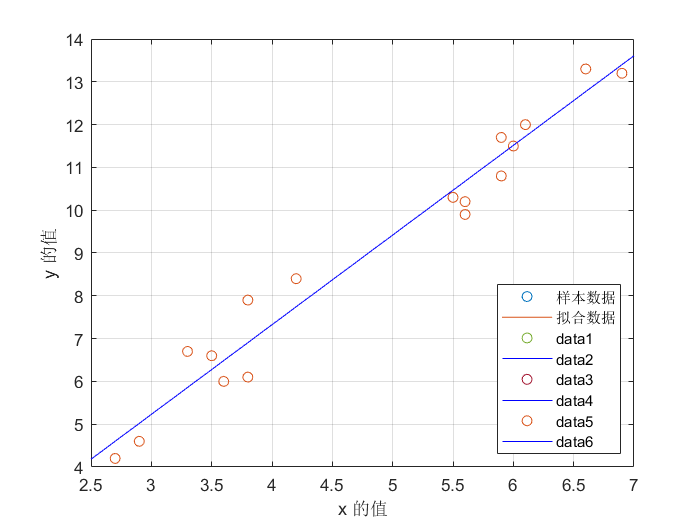

if flag == 0
    % 使用常规方式画图
    xx = 2.5 : 0.01 : 7;
    yy = k * xx + b;
    plot(xx, yy, 'b-')
else
    % 使用匿名函数画图
    f = @(x) k * x + b;
    fplot(f, [2.5, 7])
    legend('样本数据', '拟合数据', 'Location', 'SouthEast')
end


% 计算拟合优度
y_fitting = k * x + b;  % y 的拟合值
y_SSR = sum((y_fitting - mean(y_fitting)) .^ 2);  % 回归平方和 SSR
y_SSE = sum((y_fitting - y) .^ 2);  % 误差平方和
y_SST = sum((y - mean(y)) .^ 2);  % 总体平方和
%y_SST - y_SSE - y_SSR
y_R2 = y_SSR / y_SST

y_R2 = 0.9635

## 线性拟合

x = 1 : 12;
y = [5 8 9 15 25 29 31 30 22 25 27 24];

% 9 次数
a = polyfit(x, y, 9);  % 求拟合 a

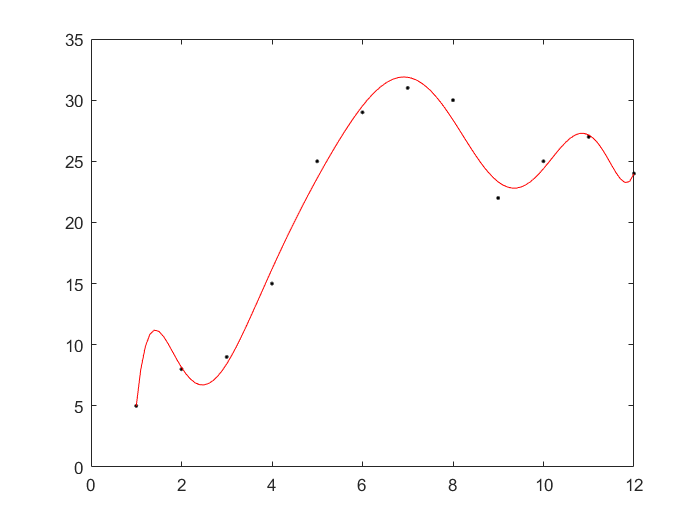


xp = 1 : 0.1 : 12;
yp = polyval(a, xp);  % 拟合预测值

plot(x, y, '.k', xp, yp, '-r');

## 非线性拟合(报错)

x = 1 : 16;
y = [4.00 6.40 8.00 8.80 9.22 9.50 9.70 9.86 10.0 10.2 10.32 10.42 10.50 10.55 10.58 10.60];

y1 = @(b, t)b(1) * exp(-t / b(2)) + b(3) * exp(-t / b(4)) + b(5);

b0 = [-1 1 -1 1 1];


rng('default')
opts = statset('nlinfit');
opts.RobustWgtFun = 'bisquare';

a = nlinfit(x, y, y1, b0, opts);

错误使用 nlinfit>checkFunVals (line 649)
您作为 MODELFUN 输入提供的函数返回了 Inf 值或 NaN 值。

出错 nlinfit>LMfit (line 620)
            if funValCheck && ~isfinite(sse), checkFunVals(r); end

出错 nlinfit (line 298)
    [beta_ls,J] = LMfit(X,y, model,beta,options,0,maxiter,


xp = 1 : 0.1 : 16;
yp = y1(a, xp);

plot(x, y, '.k', xp, yp, 'r');

错误使用 nlinfit (line 219)
MODELFUN 必须为函数，它返回大小与 Y (1-by-16)相同的拟合值向量。您提供的模型函数返回结果 1-by-1。

大小不匹配的常见原因之一是在函数中使用矩阵运算符(*、/、^)，而不是对应的元素运算符(.*、./、.^)。